# **pEllipticB**

Legendre form of the elliptic integral B

## Definition


$$B\left(\phi \left|m\right.\right)\equiv \int_0^{\phi } \frac{\cos^2 \theta \;d\theta \;}{\sqrt{1-m{\;\sin }^2 \theta }}$$



$$B\left(\phi ,k\right)\equiv B\left(\phi \left|k^2 \right.\right)$$


where $\phi \;$is the argument, *k *is the modulus,  *m *is the parameter.

Domain: $1-m\sin^2 \left(\phi \right)\ge 0$ . If $-\infty <m\le 1$ then $-\infty \le \phi \le \infty$. If $m>1$ then  $\left|\mathrm{sin}\phi \right|<1/\sqrt{m}\;$ and $|\phi |<\pi /2$ For the specified domain, the  codomain is real numbers.

Basic features:

$B\left(-\phi \left|m\right.\right)=-B\left(\phi \left|m\right.\right)$   (odd)

 $B\left(n\;\pi \pm \phi \left|m\right.\right)=2n\;B\left(m\right)\pm B\left(\phi \left|m\right.\right),\;\;\;\left|\phi \right|\le \pi /2$  (quasi-periodic)

where $B\left(m\right)$ is complete elliptic integral B .

Special values:

$B\left(0\left|m\right.\right)=0$,   $B\left(\frac{\pi }{2}\left|m\right.\right)=B\left(m\right)$

$B\left(\phi |-\infty \right)=0$,   $B\left(\phi \left|0\right.\right)=\phi$,  $B\left(\phi \left|1\right.\right)=\frac{2\phi +\mathrm{sin}\left(2\phi \right)}{4}$

Identities:


$$B\left(\phi \left|m\right.\right)=\mathit{\mathbf{B}}\left(\sin \left(\phi \right)\left|m\right.\right),\left|\phi \right|\le \pi /2$$



$$B\left(\phi |m\right)=\frac{E\left(\phi |m\right)-\left(1-m\right)F\left(\phi |m\right)}{m}$$



$$B\left(\phi |m\right)=\frac{E\left({\mathrm{sin}}^{-1} \left(\sqrt{m}\mathrm{sin}\phi \right)|m^{-1} \right)}{\sqrt{m}},\;\;m>1$$


where ***B*** is the Jacobi form of the elliptic integral *B*, *E* and *F* are the Legendre form of the elliptic integrals of 1st and 2nd kind ([3-4])

## Syntax

Y = pEllipticB(PHI,K)

y = pelB(phi,k)

Y = mpEllipticB(PHI,M)

y = mpelB(phi,m)

## Description

**Y = pEllipticB(PHI,K)** returns the Legendre form of the elliptic integral  $B\left(\phi ,k\right)$ for each element of the arrays PHI (the argment) and K (the modulus). PHI and K must be real and the same size or any of them can be scalar. **pEllipticB** is the wrapper function which calls the functions **pelB** element-wise via the function **ufun2**.

**y = pelB(phi,k)** returns the value of  the Legendre form of the elliptic integral  $B\left(\phi ,k\right)$ for the argument phi and the modulus k. It is assumed that  the input arguments are real scalars without check. y is NaN if any of   the input arguments is invalid or convergence failed. **pelB** is the wrapper function which calls the functions **mpelB**.

**Y = mpEllipticB(PHI,M)** returns the Legendre form of the elliptic integral  $B\left(\phi \left|m\right.\right)$ for each element of the arrays PHI (the argument) and M (parameter). PHI and M must be real and the same size or any of them can be scalar. **mpEllipticB** is the wrapper function which calls the functions **mpelB** element-wise via the function **ufun2**.

**y = mpelB(phi,m)** returns the value of the Legendre form of the elliptic integral $B\left(\phi \left|m\right.\right)$ for  the argument phi and the parameter m. It is assumed that the input arguments are real scalars without check. y is NaN if any of  the input arguments is invalid or convergence failed.  **mpelB **call the Carlson's functions **rf **and **rd **for calculation of $B\left(\phi \left|m\right.\right)$ ([1-2]).

## Precision

## **Numerical Examples**

**Scalar input**

format long
k = 0.5;
phi = pi/6;
[pelB(phi,k), pEllipticB(phi,k), mpelB(phi,k^2), mpEllipticB(phi,k^2)]

ans =    0.483241858284035   0.483241858284035   0.483241858284035   0.483241858284035


Accuracy. 

fprintf('%.16g\n',mpelB(pi/4,1/2)) % Maple 18D 0.6703551321060775 73

0.6703551321060776


Special values

m = 0.5;
phi = pi/9;
mpEllipticB(-phi,m) + mpEllipticB(phi,m)

ans = 0

mpEllipticB(0,m)

ans = 0

disp(mpEllipticB(pi/2,m) - mEllipticB(m))

     0



disp(pEllipticB(phi,0) - (phi/2 +sin(2*phi)/4))

     0



disp(pEllipticB(phi,1) - sin(phi))

     5.551115123125783e-17



Identities

m=-10^4;
phi = 0.499*pi; % |phi|<=pi/2
disp(mpelB(phi,m) - melB(sin(phi),m)) %  definition

     0



phi = pi/3; % |phi|<=pi/2
k = 0.5; % |k|<=1
n = 2;
disp(pelB(phi+n*pi,k)-(pelB(phi,k)+2*n*elB(k))) % periodicity

     0



k = 0.99995;
phi = pi/8;
disp(pEllipticB(phi,k) - (pelE(phi,k)-(1-k^2)*pelF(phi,k))/k^2) % deinition

    -5.551115123125783e-17



m = 2.1;
phi = 0.199*asin(1/sqrt(m));
disp(mpelB(phi,m) - mpelE(asin(sqrt(m)*sin(phi)),1/m)/sqrt(m))

     0



**Vector input**

format short
k = 0.5;
PHI = [pi/3, pi/4, 1, pi/2];
disp(pEllipticB(PHI,k) - (pEllipticE(PHI,k)-(1-k^2)*pEllipticF(PHI,k))/k^2)

   1.0e-15 *

    0.3331   -0.3331   -0.1110    0.3331



**Matrix input**

Test identity $B\left(\phi \left|m\right.\right)=\mathit{\mathbf{B}}\left(\sin \left(\phi \right)\left|m\right.\right),\left|\phi \right|\le \pi /2$

PHI = [pi/6 pi/4 3*pi/8; -pi/6 -pi/4 -3*pi/8];
M = [1/4 1 1/9; -0.1 0.2 0.1];
AER = mpEllipticB(PHI,M) - mEllipticB(sin(PHI),M)

AER =    1.0e-15 *

    0.1110         0   -0.1110
   -0.1110   -0.1110   -0.4441


## **Graphs **

**Example 1**

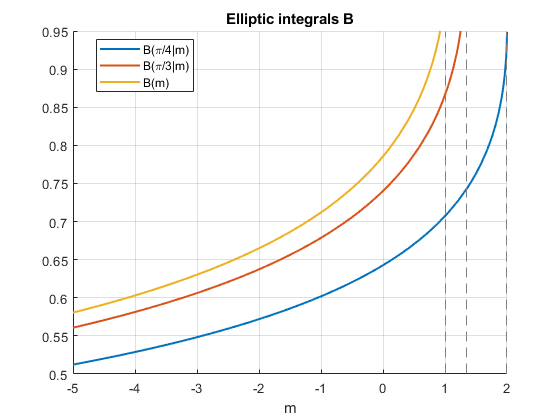

figure
hold on
fplot(@(m)mpEllipticB(pi/4, m),'LineWidth',1.5)
fplot(@(m)mpEllipticB(pi/3, m),'LineWidth',1.5)
fplot(@(m)mEllipticB(m),'LineWidth',1.5)
xlabel('m')
grid on
title('Elliptic integrals B')
legend('B(\pi/4|m)', 'B(\pi/3|m)', 'B(m)', 'Location', 'Best')
hold off

**Example 2**

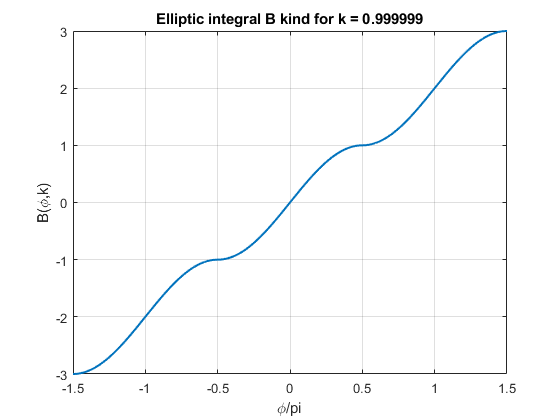

figure
phi=-1.5:0.01:1.5;
k = 0.999999;
plot(phi,pEllipticB(pi*phi,k),'LineWidth',1.5)
xlabel('\phi/pi')
ylabel('B(\phi,k)')
%xlim([-1.1 1.1])
%ylim([-3 3])
title(sprintf('Elliptic integral B kind for k = %g',k))
grid on

**Example 3**

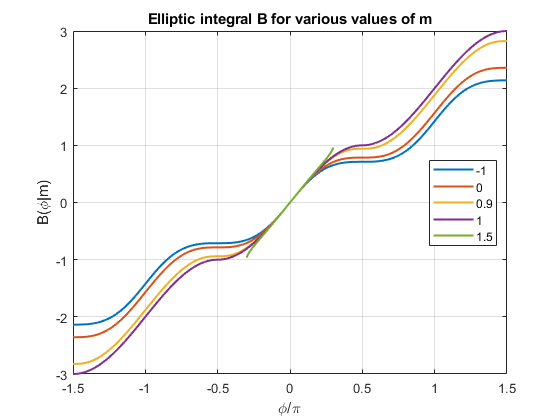

figure
PHI = -1.5:0.01:1.5;
M = [-1,0,0.9, 1,1.5];
SN = zeros(length(M),length(PHI));
clg{length(M)}=[];
for i = 1:length(M)
     clg{i} = num2str(M(i));
    SN(i,:) = mpEllipticB(pi*PHI,M(i));
end
plot(PHI,SN,'LineWidth',1.5)
axis([min(PHI) max(PHI) -3 3])
grid on
legend(clg{1:length(M)},'Location','Best')
title('Elliptic integral B for various values of m')
xlabel('\phi/\pi')
ylabel('B(\phi|m)')

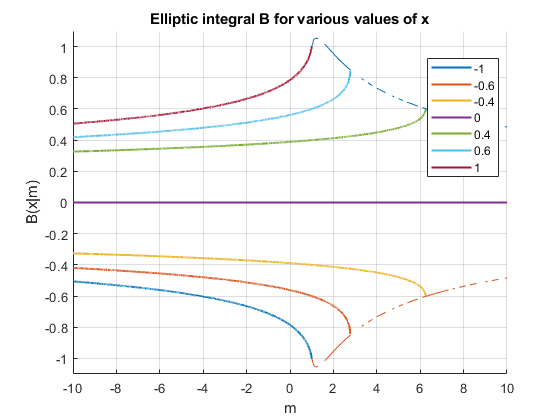

figure
hold on
M = -10:0.001:10;
X = [-1,-0.6,-0.4,0,0.4,0.6,1];
SN = zeros(length(X),length(M));
clg{length(X)}=[];
for i = 1:length(X)
     clg{i} = num2str(X(i));
    SN(i,:) = mEllipticB(X(i),M);
end
plot(M,SN,'LineWidth',1.5)
axis([min(M) max(M) -1.1 1.1])
M = 0:0.1:10;
B = mEllipticB(1./sqrt(abs(M)),M);
plot(M,B)
plot(M,-B)
grid on
legend(clg{1:length(X)},'Location','Best')
title('Elliptic integral B for various values of x')
xlabel('m')
ylabel('B(x|m)')
hold off

**Example 4**

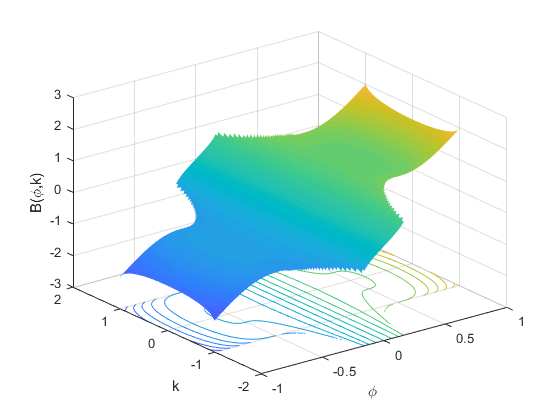

figure
phi=-1:0.01:1;
k=-2:0.01:2;
[PHI,K]=meshgrid(phi,k);
hs=surfc(PHI,K,pEllipticB(pi*PHI,K),'EdgeColor','none');
hc = hs(2);
hc.ContourZLevel = -3;
hc.LineWidth = 0.5;
hc.LevelList = -3:0.2:3;
caxis([-3 3])
view(3);
xlabel('\phi')
ylabel('k')
zlabel('B(\phi,k)')
zlim([-3 3])
grid on

**Example 5**

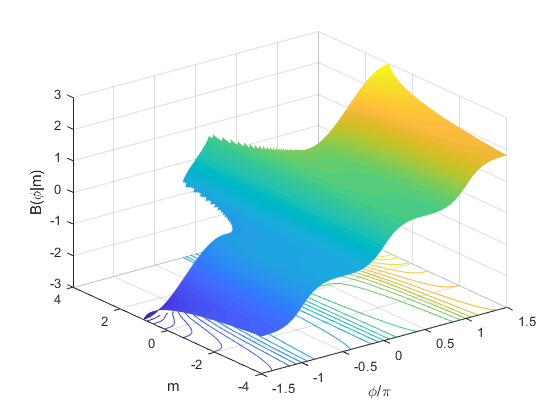

figure
phi=-1.5:0.01:1.5;
m=-4:0.01:4;
[PHI,M]=meshgrid(phi,m);
hs=surfc(PHI,M,mpEllipticB(pi*PHI,M),'EdgeColor','none');
hc = hs(2);
hc.ContourZLevel = -3;
hc.LineWidth = 0.5;
hc.LevelList = -3:0.2:3;
view(3)
caxis([-3 3])
xlabel('\phi/\pi')
ylabel('m')
zlabel('B(\phi|m)')
zlim([-3 3])
grid on

**Example 6**

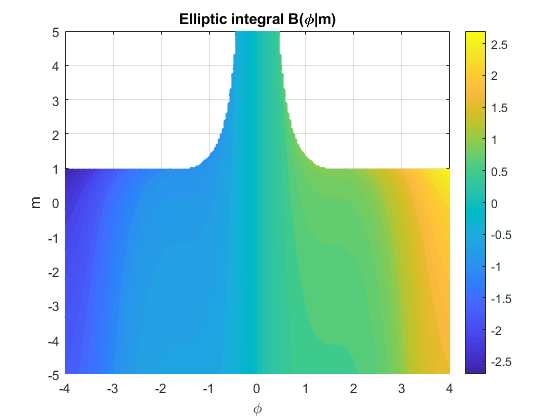

figure
f = @(phi,m)mpEllipticB(phi,m);
fcontour(f,[-4 4 -5 5],'Fill','on','LevelList',-3:0.1:3,'MeshDensity',200)
title('Elliptic integral B(\phi|m)')
colorbar
xlabel('\phi')
ylabel('m')
grid on

**Example 7**

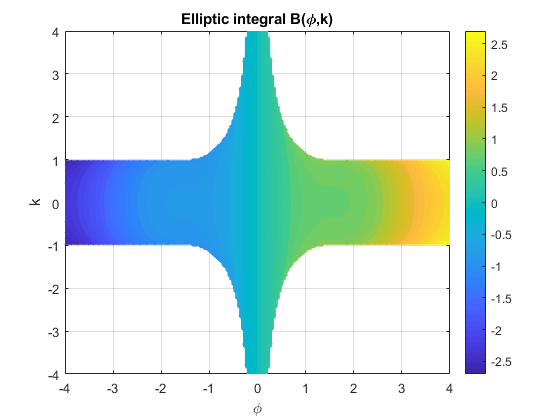

figure
f = @(phi,k)pEllipticB(phi,k);
fcontour(f,[-4 4 -4 4],'Fill','on','LevelList',-3:0.1:3,'MeshDensity',200)
title('Elliptic integral B(\phi,k)')
colorbar
xlabel('\phi')
ylabel('k')
grid on

## More About

[Abramowitz and Stegun. Handbook of Mathematical Functions](http://people.math.sfu.ca/~cbm/aands/frameindex.htm)

[Elliptic Integrals, NIST Digital Library of Mathematical Functions](https://dlmf.nist.gov/19)

[Elliptic integrals, Wikipedia](https://en.wikipedia.org/wiki/Elliptic_integral)

## **References**

[1] B.C. Carlson, Computing Elliptic Integrals by Duplication. Numerische Mathematik 33, 1-16, 1979.

[2] W.H. Press et al., Numerical Recipes, 3rd ed., Cambridge, 2007

[3] A. Erd´elyi et al., Higher Transcendental Functions Vol. II, California Institute of

Technology - Bateman Manuscript Project, 1953-1955 McGraw-Hill Inc. 

[4] E.Jahnke, F. Emde, Tables of Functions, 4th ed, Dover,  1945

## See Also